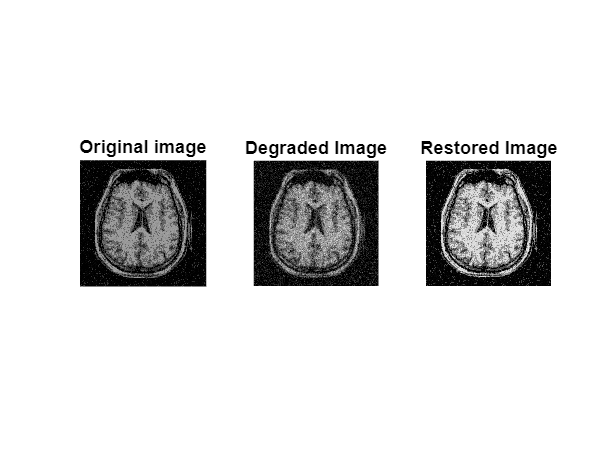

clc;clear;close all;
i=uigetfile('*.*');
I=imread(i);
f1=rgb2gray(I);
f=double(f1);

[rows,columns ]=size(f);
% Create a blurred and noisy version of the image
h = ones(3) / 9;%degradation function
F=fft2(f);
H=fft2(h,rows,columns);
N=25*randn(rows,columns);

G=F.*H ;
g=ifft2(G)+N;
subplot(1,3,1);imshow(f1);title("Original image");
subplot(1,3,2);imshow(uint8(g),[]);title("Degraded Image");

wfilter=(conj(H)./((abs(H).^2)+(abs(N).^2)./(abs(F).^2)));

final=wfilter.*G;
final1=ifft2(final);
subplot(1,3,3);imshow(uint8(final1),[]);title("Restored Image");